This file show the main functionalities of the software

## Loading the database

the 'signal_test' database contains 10 ECG recordings. Those data have been extracted from the Computer in cardiology Challenge 2011 challenge dataset A [1].  It comport 5 signals of goods quality, and 5 of bad quality (2 Gaussian noise, and 3 electrodes problem).

% load the signal
fs = 250; % the sampling frequency of the database is 250 Hz
load('signals_test.mat')


*ECGs should be vectors or matrices with leads columnwise arranged (temporal dimension in lines)*

## Assess the Quality of the Signals

ECGscorer features our novel algorithm to assess the usability of ECG signals automatically [2].

### 1 to 5 are good signals

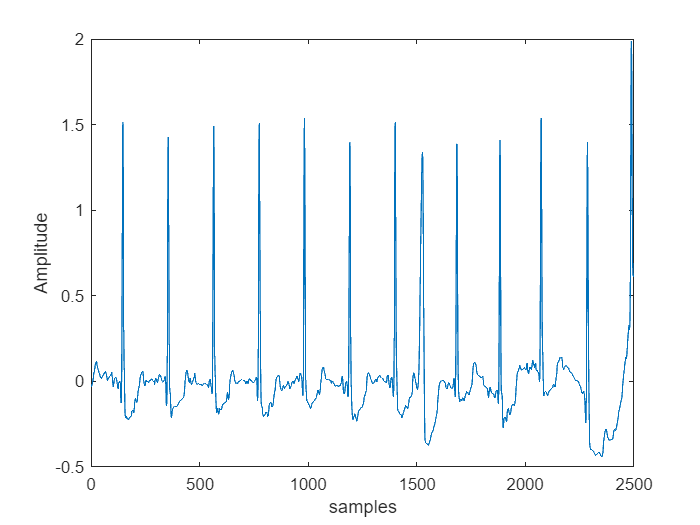

% ploting the signal
plot(signals(:,3))
xlabel('samples')
ylabel("Amplitude")

% assess the quality
[rep1, com1, sigNum] = scorer12(signals(:,1:5), 250);

********** Good Signal *************
the iscore 0.9083 the aSore is 0.9083
********** Good Signal *************
the iscore 0.85789 the aSore is 0.85789
********** Good Signal *************
the iscore 0.95807 the aSore is 0.95807
********** Good Signal *************
the iscore 0.73551 the aSore is 0.9847
********** Good Signal *************
the iscore 0.69557 the aSore is 0.98437


### 6 and 7 are gaussian noise

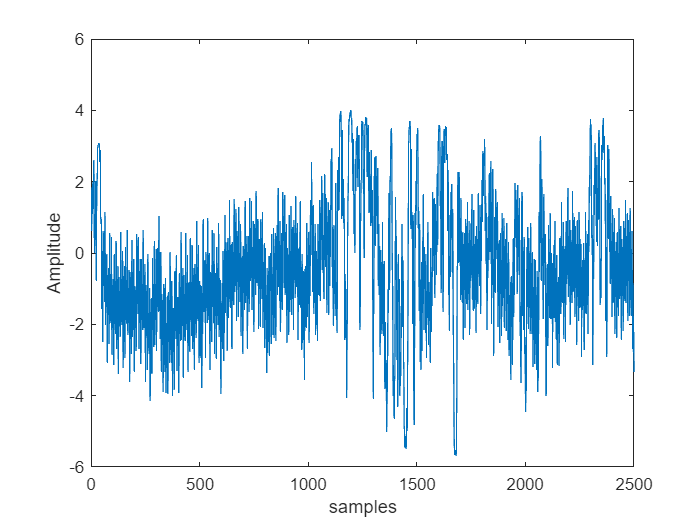

% ploting the signal
plot(signals(:,6))
xlabel('samples')
ylabel("Amplitude")

% assess the quality
[rep2, com2, sigNum2] = scorer12(signals(:,6:7), 250);

***********************
| pure noise detected |
***********************
***********************
| pure noise detected |
***********************


### 8 to 10 are saturation

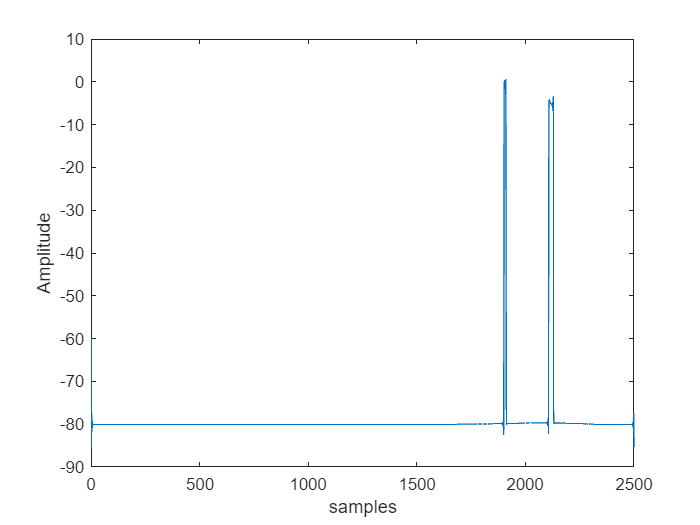

% ploting the signal
plot(signals(:,10))
xlabel('samples')
ylabel("Amplitude")


% assess the quality
rep3 = scorer12(signals(:,8:10), 250);

*******************************************************
| flat line / saturation / electrode problem detected |
*******************************************************
*******************************************************
| flat line / saturation / electrode problem detected |
*******************************************************
*******************************************************
| flat line / saturation / electrode problem detected |
*******************************************************


## Extract Signal Quality Indices

The toolbox can compute up to 37 SQIs grouped into four categories [3]: 

- 16 statistically-based (statisticSQI.m**)** 

- 9 frequency domain-based (frequencySQI.m**)**

- 7 non-linear methods based (nonLinearSQI.m**)**

- 5 QRS detectors based (qrsDetectorSQI.m**)**

### Statistics-based SQIs

#### Function

#### Examples

Example of execution for all the ECG in the database

statSQI(signals,"mean") % compute the mean off all the ECGs

ans = 10×1 table
        moy    
    ___________

     0.00092711
      7.938e-05
    -0.00028402
       0.013546
      0.0012895
       -0.42156
       -0.39291
        -45.167
      -0.012379
        -78.985


statSQI(signals,'HOS') % compute the Higher Order Statistics (skn, kurt, and hosSQI)

ans = 10×3 table
      skn        kurt      hosSQI 
    ________    ______    ________

      3.9982    23.634      18.899
      2.4074    12.261      5.9033
      3.3677    17.689      11.914
      1.3516    12.158      3.2867
     0.84166    16.911      2.8467
     0.17989     3.127      0.1125
    0.054703    3.4264    0.037487
     0.26158    1.0693    0.055945
    -0.47925    6.1432     0.58883
      8.6389    76.338      131.89


### Frequency Domain-based SQIs

#### Function

#### Examples

% compute the power of QRS over the rest of the signal for the first signal of the database
frequencySQI(signals(:,1),'psqi',fs) 

ans = table
     psqi  
    _______

    0.65436


% compute all the frequency domain based SQIs for the 3rd signal of the database
frequencySQI(signals(:,3),'all',fs) 

ans = 1×9 table
     psdl      psdh      psdn     bassqi     iorsqi     psqi       lpsqi      mpsqi       hpsqi   
    ______    ______    ______    _______    ______    _______    _______    _______    __________

    11.054    24.942    96.038    0.90321    1.0721    0.75832    0.33565    0.51656    0.00093729


### Non linear SQIs

#### Function

#### Examples

% compute the sample entropy for 7th signal
%  with default settings (m=2, and tau = 1, a = 0.2)
nonLinearSQI(signals(:,7),'samp')

ans = table
     samp 
    ______

    0.8616


% The previous statement equivalent (m=2, and tau = 1, a = 0.2)
nonLinearSQI(signals(:,7),'samp','m',2,'tau',1,'a',0.2)

ans = table
     samp 
    ______

    0.8616


% Now we compute the sample entropy for 7th signal
%  with settings (m=2, and tau = 1, a = 0.18)
nonLinearSQI(signals(:,7),'samp','m',2,'tau',1,'a',0.18)

ans = table
     samp  
    _______

    0.91897


### QRS-detector based SQIs

#### Function

#### Examples

compute the corSQI (orphanidou method [4]) for signals 1 and 2

% compute the corSQI (orphanidou method) for signals 1 and 2
qrsDetectorSQI(signals(:,1:2),'corSQI',fs)

ans = 2×1 table
    corSQI 
    _______

    0.94198
    0.91725


For instances involving Gaussian noises and saturated signals, SQIs based on QRS detectors may not be computed, as no QRS complexes are detected. In such cases, the program returns -1 for all SQIs.

% compute all qrs detectors based SQIs for 7th to 10th signal
qrsDetectorSQI(signals(:,7:10),'all',fs)

ans = 4×5 table
     tSQI      corSQI       iSQI       eSQI      pcaSQI 
    _______    _______    ________    _______    _______

    0.19682    0.44077    0.095709    0.37422    0.89548
         -1         -1          -1         -1         -1
    0.20321    0.44832    0.043918    0.47863    0.92834
         -1         -1          -1         -1         -1


## References

[1]   I. Silva, G. B. Moody, and L. Celi, ‘Improving the quality of ECGs collected using mobile phones: The PhysioNet/Computing in Cardiology Challenge 2011’, in *2011 Computing in Cardiology*, Sep. 2011, pp. 273–276.

[2]  F. Kuetche, N. Alexendre, N. E. Pascal, and S. Thierry, ‘Simple, efficient, and generalized ECG signal quality assessment method for telemedicine applications’, *Inform. Med. Unlocked*, vol. 42, p. 101375, 2023, doi: [10.1016/j.imu.2023.101375](http://doi.org/10.0.3.248/j.imu.2023.101375).

[3]  F. Kuetche, N. Alexendre, N. E. Pascal, W. Colince, and S. Thierry, ‘Signal quality indices evaluation for robust ECG signal quality assessment systems’, *Biomed. Phys. Eng. Express*, vol. 9, no. 5, p. 055016, Sep. 2023, doi: [10.1088/2057-1976/ace9e0](http://doi.org/10.0.4.64/2057-1976/ace9e0).

[4] C. Orphanidou, *Signal Quality Assessment in Physiological Monitoring: State of the Art and Practical Considerations*, 1st ed. 2018. in SpringerBriefs in Bioengineering. Cham: Springer International Publishing : Imprint: Springer, 2018